% wwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwww
% Beginning Terminal guidance STK Matlab
% wwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwww

clear all
close all
clc

global STK_version;
STK_version = 'STK11.Application';

uiApplication = actxGetRunningServer(STK_version); %change with your STK version

% Get our IAgStkObjectRoot interface
root = uiApplication.Personality2;


## Inputs

    
target = spacecraft(6371 + 1200,0,0,88,24,260);

chaser = spacecraft(6371 + 1200.05,0,0,88.01,24.02,261);

time = 60*60*0.5 %for 1 hour rendez-vous

time = 1800

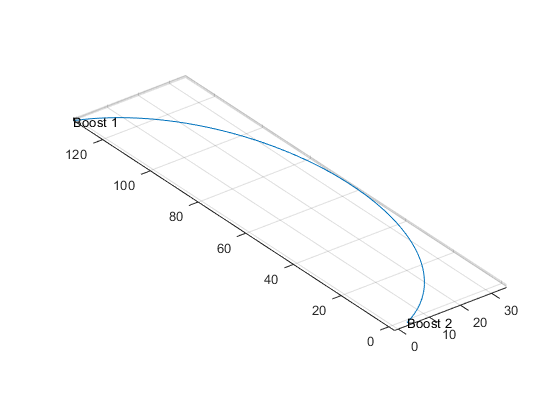


% Input initial situation
[boost, distance_end,distance_begin] = STK_simulation(target,chaser,time);


val = ['The distance to target in STK simulation is ', num2str(distance_end)];
disp(val)

The distance to target in STK simulation is 3729



val = ['The distance at the beginning in STK simulation is ', num2str(distance_begin)];
disp(val)

The distance at the beginning in STK simulation is 132232.4863



%array needed for plot
time_array_p = 1:time;
time_array_p = time_array_p';

time_array = 1:(time+1);
time_array = time_array';

## Do Clohessy Wiltshire calculation on matlab

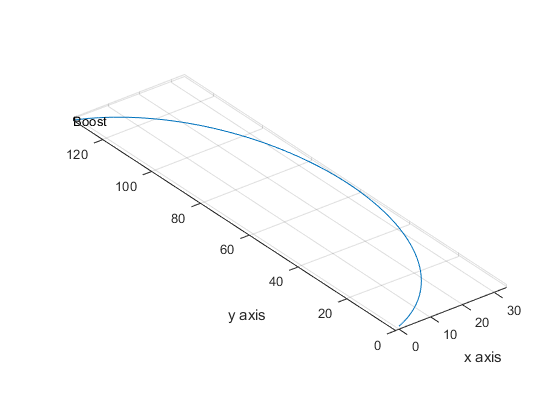

%target recon
satellite_target = root.GetObjectFromPath(strcat('Satellite/','target_oneweb'));

%chaser recon
satellite_chaser = root.GetObjectFromPath(strcat('Satellite/','satellite_chaser'));

% retrieve coordinates
root.UnitPreferences.Item('DateFormat').SetCurrentUnit('EpSec');

data_chaser_in_LVLH_chaser = satellite_target.DataProviders.GetDataPrvTimeVarFromPath('Vectors(LVLH)/satellite_chaser').Exec(root.CurrentScenario.StartTime, root.CurrentScenario.StopTime, 1);

data_chaser_X = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('x').GetValues);
data_chaser_Y = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('y').GetValues);
data_chaser_Z = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('z').GetValues);

data_chaser_Vx = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('Derivative x').GetValues);
data_chaser_Vy = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('Derivative y').GetValues);
data_chaser_Vz = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('Derivative z').GetValues);

data_target_inertial = satellite_chaser.DataProviders.Item('Astrogator Values').Group.Item('Cartesian Elems').Exec(root.CurrentScenario.StartTime,root.CurrentScenario.StopTime,1);

dataXc = cell2mat(data_target_inertial.DataSets.GetDataSetByName('X').GetValues);
dataYc = cell2mat(data_target_inertial.DataSets.GetDataSetByName('Y').GetValues);
dataZc = cell2mat(data_target_inertial.DataSets.GetDataSetByName('Z').GetValues);

dataVXc = cell2mat(data_target_inertial.DataSets.GetDataSetByName('Vx').GetValues);
dataVYc = cell2mat(data_target_inertial.DataSets.GetDataSetByName('Vy').GetValues);
dataVZc = cell2mat(data_target_inertial.DataSets.GetDataSetByName('Vz').GetValues);


dR0 = [data_chaser_X(1,1) data_chaser_Y(1,1) data_chaser_Z(1,1)];
dV0 = [data_chaser_Vx(1,1) data_chaser_Vy(1,1) data_chaser_Vz(1,1)];

vA0targ = [dataVXc(1,1) dataVYc(1,1) dataVZc(1,1)];
rA0targ = [dataXc(1,1) dataYc(1,1) dataZc(1,1)];

%calculation of the CW matrix
t = time; %pour x heures
n = norm(vA0targ)/norm(rA0targ);  %rad/s

Irr = [4-3*cos(n*t) 0 0 ; 6*(sin(n*t)-n*t) 1 0 ; 0 0 cos(n*t)];
Irv = [(1/n)*sin(n*t) (2/n)*(1-cos(n*t)) 0 ; (2/n)*(cos(n*t)-1) (1/n)*(4*sin(n*t)-3*n*t) 0 ; 0 0 (1/n)*sin(n*t)];
Ivr = [3*n*sin(n*t) 0 0 ; 6*n*(cos(n*t)-1) 0 0 ; 0 0 -n*sin(n*t)];
Ivv = [cos(n*t) 2*sin(n*t) 0 ; -2*sin(n*t) 4*cos(n*t)-3 0 ; 0 0 cos(n*t)];

dV0_plus = -inv(Irv)*Irr*dR0';

dV0_min = dV0';


for t = 1:time % pour x heures
    
    Irr = [4-3*cos(n*t) 0 0 ; 6*(sin(n*t)-n*t) 1 0 ; 0 0 cos(n*t)];
    Irv = [(1/n)*sin(n*t) (2/n)*(1-cos(n*t)) 0 ; (2/n)*(cos(n*t)-1) (1/n)*(4*sin(n*t)-3*n*t) 0 ; 0 0 (1/n)*sin(n*t)];
    Posi = Irr*dR0' + Irv*dV0_plus;
    Position(t,:)= (Posi)';
end


%figure CW matlab
figure()
plot3(Position(:,1),Position(:,2),Position(:,3))
axis equal
grid on
xlabel('x axis')
ylabel('y axis')
zlabel('z axis')
text (Position(1,1), Position(1,2), Position(1,3), "Boost")

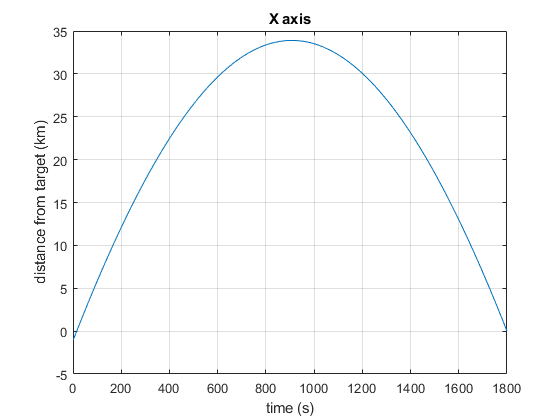

%text (Position(time,1), Position(time,2), Position(time,3), "Boost 2")

%x
figure()
plot(time_array_p,Position(:,1))
grid on
xlabel('time (s)')
ylabel('distance from target (km)')
title('X axis')

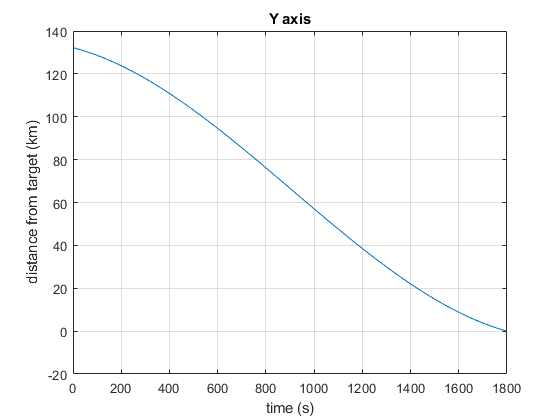

%y
figure()
plot(time_array_p,Position(:,2))
grid on
xlabel('time (s)')
ylabel('distance from target (km)')
title('Y axis')

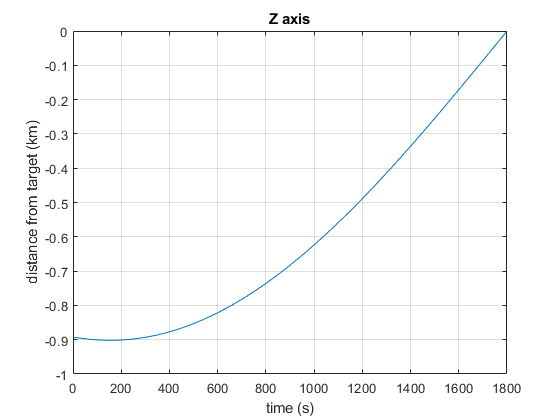

%z
figure()
plot(time_array_p,Position(:,3))
grid on
xlabel('time (s)')
ylabel('distance from target (km)')
title('Z axis')

## Get STK simulation

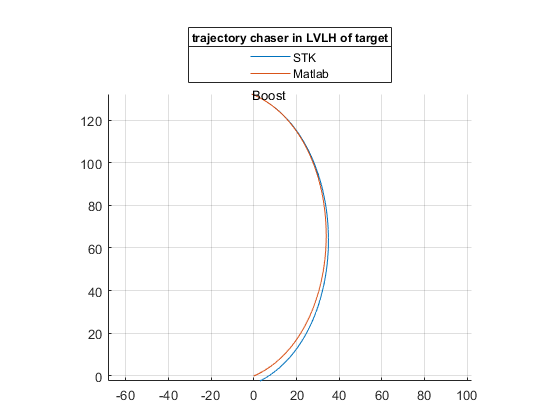

figure()
hold on
plot3(data_chaser_X(:,1),data_chaser_Y(:,1),data_chaser_Z(:,1))
plot3(Position(:,1),Position(:,2),Position(:,3))
axis equal
grid on
lgd = legend('STK','Matlab');
lgd.Location = 'northoutside';
title(lgd,'trajectory chaser in LVLH of target')
text (data_chaser_X(1,1), data_chaser_Y(1,1), data_chaser_Z(1,1), "Boost")

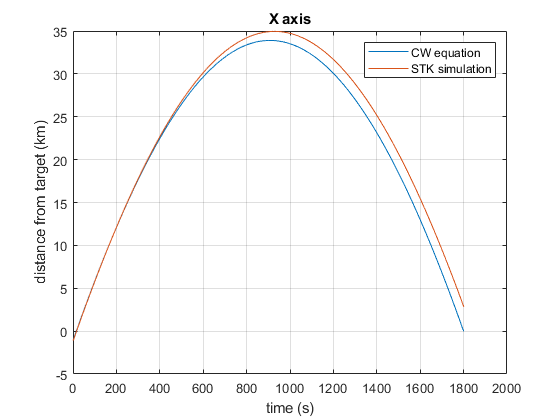




%x
figure()
plot(time_array_p,Position(:,1),time_array,data_chaser_X(:,1))
grid on
lgd = legend('CW equation','STK simulation');
xlabel('time (s)')
ylabel('distance from target (km)')
title('X axis')

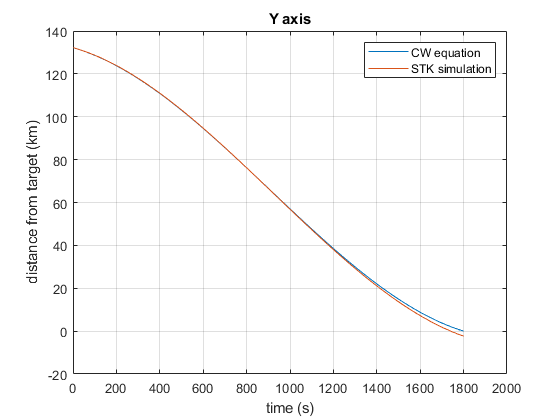

%y
figure()
plot(time_array_p,Position(:,2),time_array,data_chaser_Y(:,1))
grid on
lgd = legend('CW equation','STK simulation');
xlabel('time (s)')
ylabel('distance from target (km)')
title('Y axis')

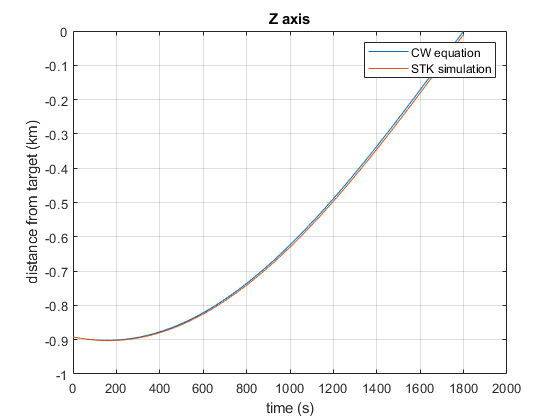

%z
figure()
plot(time_array_p,Position(:,3),time_array,data_chaser_Z(:,1))
grid on
lgd = legend('CW equation','STK simulation');
xlabel('time (s)')
ylabel('distance from target (km)')
title('Z axis')

## Improve with Genetic Algorithm

DV = load('Best_boost.mat');

[boost_ge, distance_end_ge] = GENalg_STK_simulation(DV.Best_boost,target,chaser,time);

%target recon
satellite_target = root.GetObjectFromPath(strcat('Satellite/','target_oneweb'));
%chaser recon
satellite_chaser = root.GetObjectFromPath(strcat('Satellite/','satellite_chaser'));

% retrieve coordinates
root.UnitPreferences.Item('DateFormat').SetCurrentUnit('EpSec');

data_chaser_in_LVLH_chaser = satellite_target.DataProviders.GetDataPrvTimeVarFromPath('Vectors(LVLH)/satellite_chaser').Exec(root.CurrentScenario.StartTime, root.CurrentScenario.StopTime, 1);

data_chaser_X_GE = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('x').GetValues);
data_chaser_Y_GE = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('y').GetValues);
data_chaser_Z_GE = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('z').GetValues);

%data_chaser_Vx = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('Derivative x').GetValues);
%data_chaser_Vy = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('Derivative y').GetValues);
%data_chaser_Vz = cell2mat(data_chaser_in_LVLH_chaser.DataSets.GetDataSetByName('Derivative z').GetValues);

val = ['The distance to target with GE algorithm is ', num2str(distance_end_ge)];
disp(val)

The distance to target with GE algorithm is 11


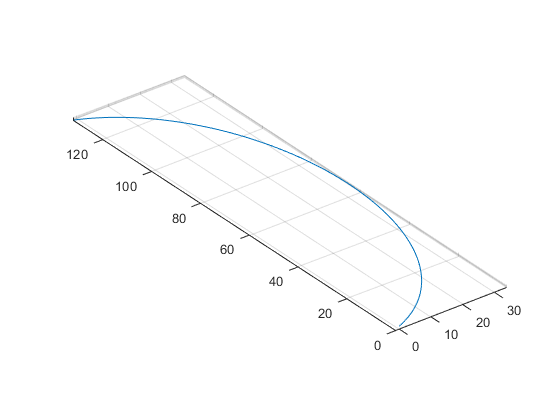


figure()
plot3(data_chaser_X_GE(:,1),data_chaser_Y_GE(:,1),data_chaser_Z_GE(:,1))
axis equal
grid on

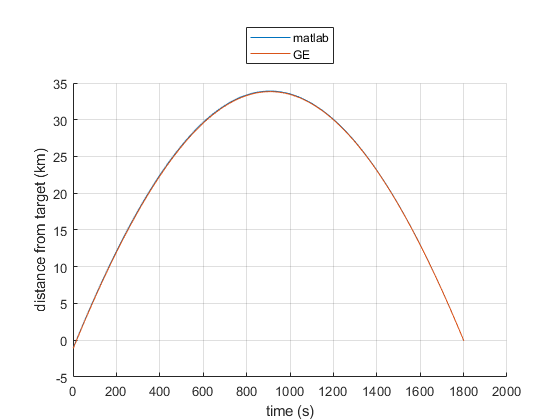


%x
figure()
hold on
plot(time_array_p,Position(:,1),time_array,data_chaser_X_GE)
%axis equal
grid on
xlabel('time (s)')
ylabel('distance from target (km)')
lgd = legend('matlab','GE');
lgd.Location = 'northoutside';

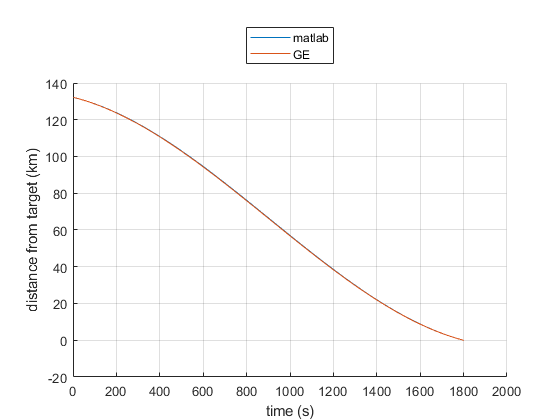

%title(lgd,'trajectory chaser in LVLH of target')

%y
figure()
hold on
plot(time_array_p,Position(:,2),time_array,data_chaser_Y_GE)
%axis equal
grid on
xlabel('time (s)')
ylabel('distance from target (km)')
lgd = legend('matlab','GE');
lgd.Location = 'northoutside';

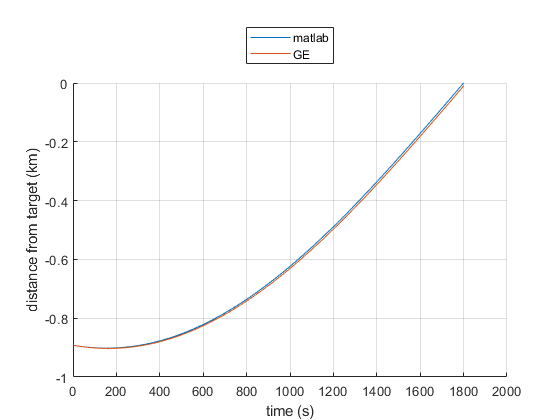

%title(lgd,'trajectory chaser in LVLH of target')

%Z
figure()
hold on
plot(time_array_p,Position(:,3),time_array,data_chaser_Z_GE)
%axis equal
grid on
xlabel('time (s)')
ylabel('distance from target (km)')
lgd = legend('matlab','GE');
lgd.Location = 'northoutside';

%title(lgd,'trajectory chaser in LVLH of target')

## Final graph

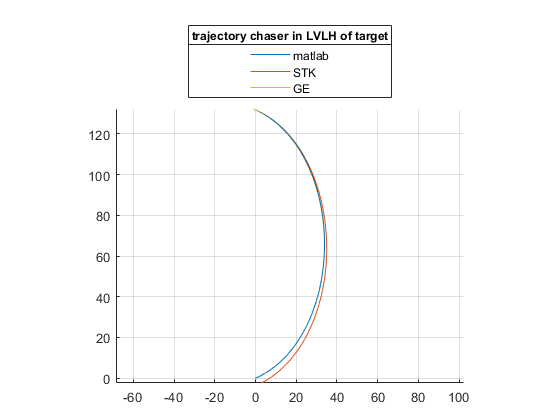

figure()
hold on
plot3(Position(:,1),Position(:,2),Position(:,3))
plot3(data_chaser_X(:,1),data_chaser_Y(:,1),data_chaser_Z(:,1))
plot3(data_chaser_X_GE(:,1),data_chaser_Y_GE(:,1),data_chaser_Z_GE(:,1))
axis equal
grid on
lgd = legend('matlab','STK','GE');
lgd.Location = 'northoutside';
title(lgd,'trajectory chaser in LVLH of target')

## See difference

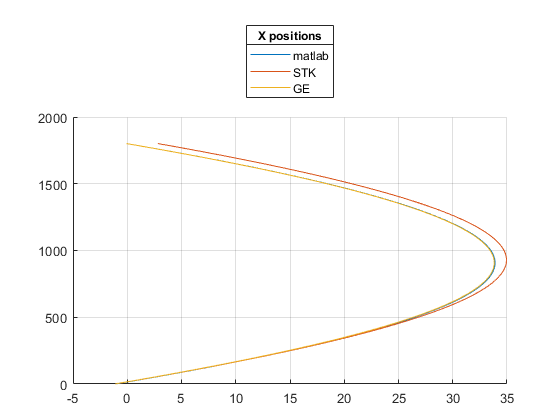


% X position axis
figure()
hold on
plot(Position(:,1),time_array_p)
plot(data_chaser_X(:,1),time_array)
plot(data_chaser_X_GE(:,1),time_array)
%axis equal
grid on
lgd = legend('matlab','STK','GE');
lgd.Location = 'northoutside';
title(lgd,'X positions')

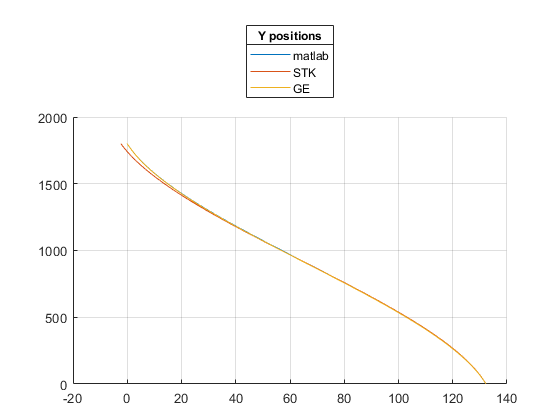


% Y position axis
figure()
hold on
plot(Position(:,2),time_array_p)
plot(data_chaser_Y(:,1),time_array)
plot(data_chaser_Y_GE(:,1),time_array)
%axis equal
grid on
lgd = legend('matlab','STK','GE');
lgd.Location = 'northoutside';
title(lgd,'Y positions')

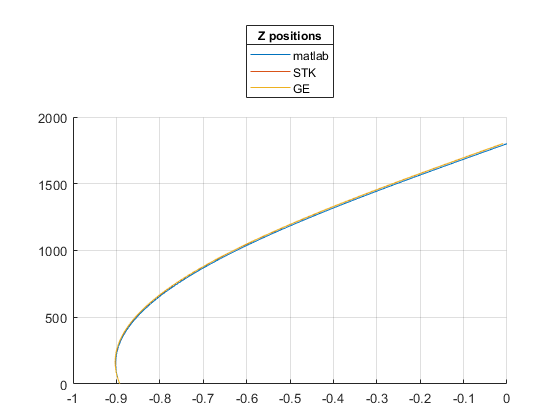


% Z position axis
figure()
hold on
plot(Position(:,3),time_array_p)
plot(data_chaser_Z(:,1),time_array)
plot(data_chaser_Z_GE(:,1),time_array)
%axis equal
grid on
lgd = legend('matlab','STK','GE');
lgd.Location = 'northoutside';
title(lgd,'Z positions')

## difference from matlab

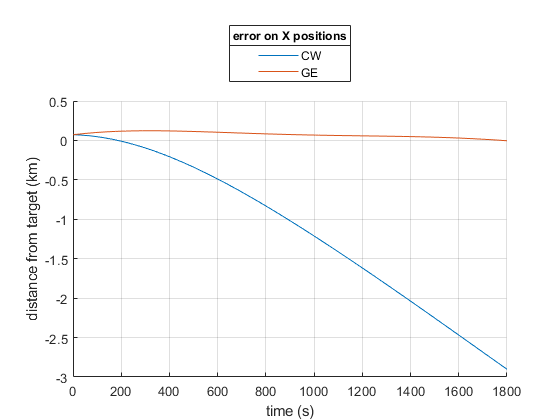

data_stk_dif = zeros(time,3);

data_ge_dif = zeros(time,3);


for i = 1:time
    data_stk_dif(i,1) = Position(i,1) - data_chaser_X(i,1);
    data_stk_dif(i,2) = Position(i,2) - data_chaser_Y(i,1);
    data_stk_dif(i,3) = Position(i,3) - data_chaser_Z(i,1);
    
    data_ge_dif(i,1) = Position(i,1) - data_chaser_X_GE(i,1);
    data_ge_dif(i,2) = Position(i,2) - data_chaser_Y_GE(i,1);
    data_ge_dif(i,3) = Position(i,3) - data_chaser_Z_GE(i,1);
end


% X position axis
figure()
hold on
plot(time_array_p,data_stk_dif(:,1))
plot(time_array_p,data_ge_dif(:,1))
%axis equal
grid on
ylabel('distance from target (km)');
xlabel('time (s)');
lgd = legend('CW','GE');
lgd.Location = 'northoutside';
title(lgd,'error on X positions')

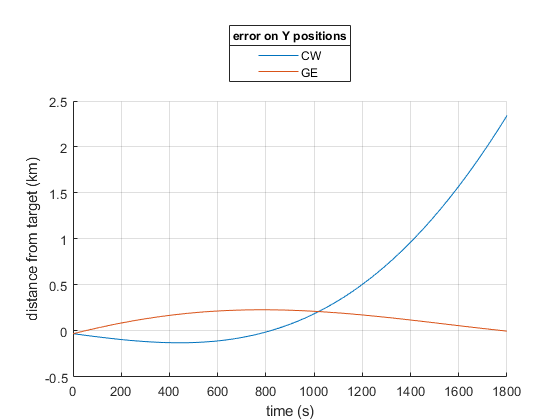


% Y position axis
figure()
hold on
plot(time_array_p,data_stk_dif(:,2))
plot(time_array_p,data_ge_dif(:,2))
%axis equal
grid on
ylabel('distance from target (km)');
xlabel('time (s)');
lgd = legend('CW','GE');
lgd.Location = 'northoutside';
title(lgd,'error on Y positions')

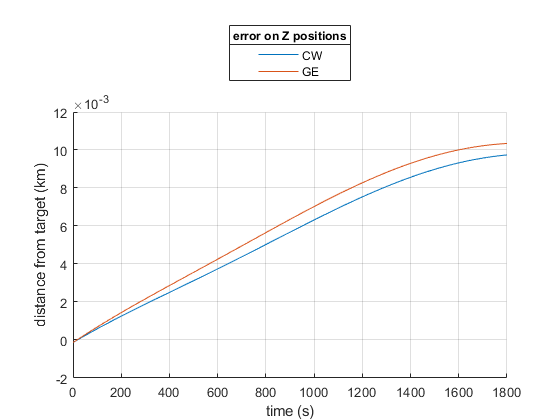


% Z position axis
figure()
hold on
plot(time_array_p,data_stk_dif(:,3))
plot(time_array_p,data_ge_dif(:,3))
%axis equal
grid on
ylabel('distance from target (km)');
xlabel('time (s)');
lgd = legend('CW','GE');
lgd.Location = 'northoutside';
 title(lgd,'error on Z positions')